# Hierarchical Risk Parity Test File

#### Author: Nina Matthews

#### Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities

#### Last edit: 25/02/2023

#### Supervisor: A/Prof. Tim Gebbie

**Resources Used: **The MathWorks, Inc. (2019)  &  Marcos Lopez De Prado (2016) (*See reference list below)*

## **Purpose:**

This file tests *Fn_HRP_estimate() *using dummy data of a 10 asset case. 

## Data:

The data of the 10 assset case is based on the simulated data that was generated in De Prodo's python code chunk that he defined in his 2016 paper. However, in the subsequent years, Python made a fundemental change in how their random generator functions work so the data was not fully retievable. This issue was overcome by sourcing the data from Kipnis when he replicated the data in 2017 before the change was made.  

## Validation:

The functions and additional code is validated by using the test data as well as output generatied using the R programming language to compare output weights. The results show that both languages produce the same output, and both match De Prado's results.

#### Clear Env and Plots

clc % clear command window
close all %clear all figs
clear % clears workspace

#### Paths

Use your user path and folders to specify the correct path using absolute paths

% use your default user path to create the filename and path
fileName = 'Kipnis_covMat.csv';
fileName = fullfile('/Users/Ninamatthews/Desktop/MASTERS/DISSERTATION Code/Toolboxes/hrp/test_code',fileName);

% Add /functions directory 
addpath('functions');

## Test

#### Load data

The dataset is simulated that some assets are closely correlated.

assetcov_csv = readtable(fileName);

Visualise data using a heatmap. Note: same profile as seen through R but the ordering is 1 to 10 descending whilst this is reversed when displayed in R.

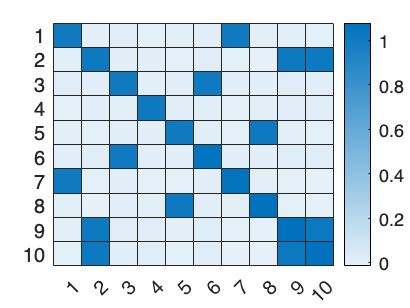

% Import data and convert to matrix
cov_10_asset = readmatrix(fileName);
cov = (cov_10_asset); % Flip columns and transpose
% Display heatmap
heatmap(cov);

Apply our HRP function.

w_hrp = hrpestimate(cov_10_asset)

wgtHRP =     0.0700
    0.0759
    0.1084
    0.1903
    0.0972
    0.1019
    0.0662
    0.0910
    0.0712
    0.1279


Output confirmed against R output as well as De Prado's results in his principle paper on HRP.

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)

- [https://en.wikipedia.org/wiki/Risk_parity](https://en.wikipedia.org/wiki/Risk_parity)